# DK e IK SCARA

clc
clear all
close all
addpath('/home/laura/Documents/MATLAB/')


Definición de Parámetros 

% Medidas en cm
d1 = 225; 
d2 = 175; 
d3 = 163.6; 
d4 = 0; 
d5 = -50; 
d6 = 73; 
L = 20; 

th1 = 0; 
th2 = 0; 
th3 = 0; 

syms d1 d2 d3 d4 d5 d6 av th1 th2 th3 real

aij = [0 d1 d2 0 0 0]; 
alphaij = [0 0 pi 0 0 0];
sj = [d3 d4 d5 0 (d6 + av*th3/(2*pi())) 0]; 
thetaj = [th1 th2 th3 -th3 0 0];
DH = [aij', alphaij', sj', thetaj']

$$DH = \left(\begin{array}{cccc} 0 & 0 & d_{3} & {\mathrm{th}}_{1}\\ d_{1} & 0 & d_{4} & {\mathrm{th}}_{2}\\ d_{2} & \pi & d_{5} & {\mathrm{th}}_{3}\\ 0 & 0 & 0 & -{\mathrm{th}}_{3}\\ 0 & 0 & d_{6}+\frac{\mathrm{av}\,{\mathrm{th}}_{3}}{2\,\pi } & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$


frame=size(DH,1);

#### Transformada DH

for i=1:frame
    T_ij(:,:,i)=T_DH(DH(i,1),DH(i,2),DH(i,3),DH(i,4)); %Saca todos los frames respecto a un marco local
end
T(:,:,1)=T_ij(:,:,1);
for i=1:frame-1
    T(:,:,i+1)=T(:,:,i)*T_ij(:,:,i+1); % Transformacones de traslación y rotación (premult)
end
simplify(T(:,:,end))

$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right) & \sin\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right) & 0 & d_{2}\,\cos\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right)+d_{1}\,\cos\left({\mathrm{th}}_{1}\right)\\ \sin\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right) & -\cos\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right) & 0 & d_{2}\,\sin\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right)+d_{1}\,\sin\left({\mathrm{th}}_{1}\right)\\ 0 & 0 & -1 & d_{3}+d_{4}-d_{5}-d_{6}-\frac{\mathrm{av}\,{\mathrm{th}}_{3}}{2\,\pi }\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Gráfica

T_syms = T;
T = double(subs(T, [d1 d2 d3 d4 d5 d6 av th1 th2 th3], ...
    [225 175 163.6 0 -50 73 8 0 0 0]))

T = T(:,:,1) =

    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000  163.6000
         0         0         0    1.0000


T(:,:,2) =

    1.0000         0         0  225.0000
         0    1.0000         0         0
         0         0    1.0000  163.6000
         0         0         0    1.0000


T(:,:,3) =

    1.0000         0         0  400.0000
         0   -1.0000         0         0
         0         0   -1.0000  213.6000
         0         0         0    1.0000


T(:,:,4) =

    1.0000         0         0  400.0000
         0   -1.0000         0         0
         0         0   -1.0000  213.6000
         0         0         0    1.0000


T(:,:,5) =

    1.0000         0         0  400.0000
         0   -1.0000         0         0
         0         0   -1.0000  140.6000
         0         0         0    1.0000


T(:,:,6) =

    1.0000         0         0  400.0000
         0   -1.0000         0         0
         0  

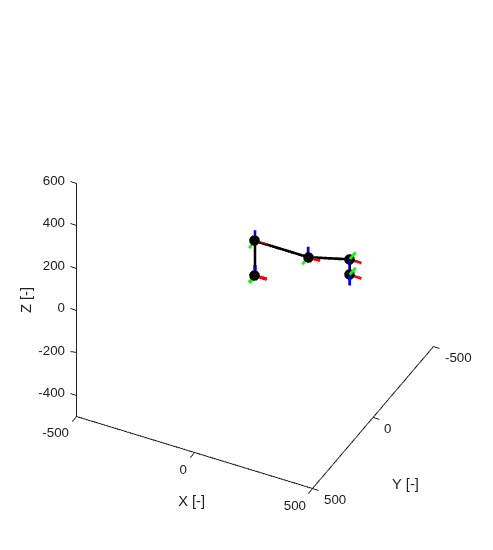


% Define the Fixed Frame
hf=figure(1);
set(hf,'position',[445   275   563   628])
% Unit vectors scale factor(visual)
L=50;
h_ejexF=plot3([0 L],[0 0],[0 0],'r','linewidth',2.5);
hold on
h_ejeyF=plot3([0 0],[0 L],[0 0],'g','linewidth',2.5);
hold on
h_ejezF=plot3([0 0],[0 0],[0 L],'b','linewidth',2.5);
hold on
axis equal
axis([-500 500 -500 500 -500 600])
xlabel('X [-]')
ylabel('Y [-]')
zlabel('Z [-]')
view(-27,-37)
% Mobile Coordinate System Based on DoF
for i=1:frame
    h_ejexM(i,1)=plot3([0 0],[0 0],[0 0],'r','linewidth',2);
    hold on
    h_ejeyM(i,1)=plot3([0 0],[0 0],[0 0],'g','linewidth',2);
    hold on
    h_ejezM(i,1)=plot3([0 0],[0 0],[0 0],'b','linewidth',2);
end
% Points Matrix on {j}
Mp=[0,0,0,1;
    L,0,0,1;
    0,L,0,1;
    0,0,L,1];
% Points Matrix on {0}
for k=1:frame
    for i=1:4
        Mp_T(i,:,k)=(T(:,:,k)*Mp(i,:)')'; % MARCO GLOBAL
    end
end
% Plot each Coordinate System in the Global Frame
for k=1:frame
    set(h_ejexM(k,1),'xdata',[Mp_T(1,1,k) Mp_T(2,1,k)],...
        'ydata',[Mp_T(1,2,k) Mp_T(2,2,k)],...
        'zdata',[Mp_T(1,3,k) Mp_T(2,3,k)])
    set(h_ejeyM(k,1),'xdata',[Mp_T(1,1,k) Mp_T(3,1,k)],...
        'ydata',[Mp_T(1,2,k) Mp_T(3,2,k)],...
        'zdata',[Mp_T(1,3,k) Mp_T(3,3,k)])
    set(h_ejezM(k,1),'xdata',[Mp_T(1,1,k) Mp_T(4,1,k)],...
        'ydata',[Mp_T(1,2,k) Mp_T(4,2,k)],...
        'zdata',[Mp_T(1,3,k) Mp_T(4,3,k)])
end

% Extract Origins: [Base (0,0,0) -> Frame 1 -> Frame 2 -> ...]
P = [0 0 0; squeeze(T(1:3,4,:))']; 

% GRaph the links
plot3(P(:,1), P(:,2), P(:,3), 'k-o', 'LineWidth', 2, 'MarkerFaceColor', 'k');

#### **Cinemática Inversa - Deducción**

syms th1 th2 th3 real             % re-declara por si quedaron sobrescritos en el workspace
syms rx ry rz real
syms c1 s1 c2 s2 codo real

P = simplify(T_syms(1:3,4,end));  % posición de la herramienta según la DK
r = [rx; ry; rz];                 % posición deseada

eq = P == r                       % las 3 ecuaciones a resolver

$$eq = \left(\begin{array}{c} d_{2}\,\cos\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right)+d_{1}\,\cos\left({\mathrm{th}}_{1}\right)=\mathrm{rx}\\ d_{2}\,\sin\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right)+d_{1}\,\sin\left({\mathrm{th}}_{1}\right)=\mathrm{ry}\\ d_{3}+d_{4}-d_{5}-d_{6}-\frac{\mathrm{av}\,{\mathrm{th}}_{3}}{2\,\pi }=\mathrm{rz} \end{array}\right)$$


%% ---- th2: suma de cuadrados de x, y ----
lhs = simplify(expand(P(1)^2 + P(2)^2))   % -> d1^2 + d2^2 + 2*d1*d2*cos(th2)

$$lhs = {d_{1}}^{2}+2\,\cos\left({\mathrm{th}}_{2}\right)\,d_{1}\,d_{2}+{d_{2}}^{2}$$

rhs = rx^2 + ry^2;

lhs = subs(lhs, cos(th2), c2);
c2  = simplify(solve(lhs == rhs, c2))     % -> (rx^2 + ry^2 - d1^2 - d2^2)/(2*d1*d2)

$$c2 = -\frac{{d_{1}}^{2}+{d_{2}}^{2}-{\mathrm{rx}}^{2}-{\mathrm{ry}}^{2}}{2\,d_{1}\,d_{2}}$$

s2  = codo*sqrt(1 - c2^2)                 % convierte de coseno a seno

$$s2 = \mathrm{codo}\,\sqrt{1-\frac{{\left({d_{1}}^{2}+{d_{2}}^{2}-{\mathrm{rx}}^{2}-{\mathrm{ry}}^{2}\right)}^{2}}{4\,{d_{1}}^{2}\,{d_{2}}^{2}}}$$

th2_ = atan2(s2, c2)                      % (si |c2| > 1 -> fuera de alcance)

$$th2\_ = \text{atan2}\left(2\,\mathrm{codo}\,\sqrt{1-\frac{{\left({d_{1}}^{2}+{d_{2}}^{2}-{\mathrm{rx}}^{2}-{\mathrm{ry}}^{2}\right)}^{2}}{4\,{d_{1}}^{2}\,{d_{2}}^{2}}},-\frac{{d_{1}}^{2}+{d_{2}}^{2}-{\mathrm{rx}}^{2}-{\mathrm{ry}}^{2}}{d_{1}\,d_{2}}\right)$$


%% ---- th1: solución matricial A*x = b ----
syms c2_ s2_ real                         % c2, s2 como incógnitas ya conocidas
Pxy = expand(P(1:2));                     % separa cos(th1+th2) y sin(th1+th2)
Pxy = subs(Pxy, [cos(th1) sin(th1) cos(th2) sin(th2)], [c1 s1 c2_ s2_]);

A = jacobian(Pxy, [c1 s1])                % -> [d1 + d2*c2, -d2*s2;  d2*s2, d1 + d2*c2]

$$A = \left(\begin{array}{cc} d_{1}+c_{\mathrm{2\_}}\,d_{2} & -d_{2}\,s_{\mathrm{2\_}}\\ d_{2}\,s_{\mathrm{2\_}} & d_{1}+c_{\mathrm{2\_}}\,d_{2} \end{array}\right)$$

resto = simplify(Pxy - A*[c1; s1])        % debe dar [0; 0]

$$resto = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

b = [rx; ry] - resto;

x = simplify(A \ b)                       % -> [c1; s1]

$$x = \left(\begin{array}{c} \frac{d_{1}\,\mathrm{rx}+c_{\mathrm{2\_}}\,d_{2}\,\mathrm{rx}+d_{2}\,\mathrm{ry}\,s_{\mathrm{2\_}}}{{c_{\mathrm{2\_}}}^{2}\,{d_{2}}^{2}+2\,c_{\mathrm{2\_}}\,d_{1}\,d_{2}+{d_{1}}^{2}+{d_{2}}^{2}\,{s_{\mathrm{2\_}}}^{2}}\\ \frac{d_{1}\,\mathrm{ry}+c_{\mathrm{2\_}}\,d_{2}\,\mathrm{ry}-d_{2}\,\mathrm{rx}\,s_{\mathrm{2\_}}}{{c_{\mathrm{2\_}}}^{2}\,{d_{2}}^{2}+2\,c_{\mathrm{2\_}}\,d_{1}\,d_{2}+{d_{1}}^{2}+{d_{2}}^{2}\,{s_{\mathrm{2\_}}}^{2}} \end{array}\right)$$

detA = simplify(det(A))                   % = rx^2 + ry^2 (singular si el punto está en el eje de la base)

$$detA = {c_{\mathrm{2\_}}}^{2}\,{d_{2}}^{2}+2\,c_{\mathrm{2\_}}\,d_{1}\,d_{2}+{d_{1}}^{2}+{d_{2}}^{2}\,{s_{\mathrm{2\_}}}^{2}$$

th1_ = atan2(x(2), x(1))                  % th1 en función de c2_, s2_

$$th1\_ = \begin{array}{l} \text{atan2}\left(\frac{d_{1}\,\mathrm{ry}+c_{\mathrm{2\_}}\,d_{2}\,\mathrm{ry}-d_{2}\,\mathrm{rx}\,s_{\mathrm{2\_}}}{\sigma_{1}},\frac{d_{1}\,\mathrm{rx}+c_{\mathrm{2\_}}\,d_{2}\,\mathrm{rx}+d_{2}\,\mathrm{ry}\,s_{\mathrm{2\_}}}{\sigma_{1}}\right)\\ \mathrm{where}\\ \sigma_{1}={c_{\mathrm{2\_}}}^{2}\,{d_{2}}^{2}+2\,c_{\mathrm{2\_}}\,d_{1}\,d_{2}+{d_{1}}^{2}+{d_{2}}^{2}\,{s_{\mathrm{2\_}}}^{2} \end{array}$$

th1_ = simplify(subs(th1_, [c2_ s2_], [c2 s2]))   % th1 solo en función de rx, ry y medidas

$$th1\_ = \text{angle}\left(\frac{d_{1}\,\left(\mathrm{rx}+\mathrm{ry}\,\mathrm{i}\right)\,\left({d_{1}}^{2}-{d_{2}}^{2}+{\mathrm{rx}}^{2}+{\mathrm{ry}}^{2}-2\,\mathrm{codo}\,d_{1}\,d_{2}\,\sqrt{1-\frac{{\left({d_{1}}^{2}+{d_{2}}^{2}-{\mathrm{rx}}^{2}-{\mathrm{ry}}^{2}\right)}^{2}}{4\,{d_{1}}^{2}\,{d_{2}}^{2}}}\,\mathrm{i}\right)}{-{\mathrm{codo}}^{2}\,{d_{1}}^{4}+2\,{\mathrm{codo}}^{2}\,{d_{1}}^{2}\,{d_{2}}^{2}+2\,{\mathrm{codo}}^{2}\,{d_{1}}^{2}\,{\mathrm{rx}}^{2}+2\,{\mathrm{codo}}^{2}\,{d_{1}}^{2}\,{\mathrm{ry}}^{2}-{\mathrm{codo}}^{2}\,{d_{2}}^{4}+2\,{\mathrm{codo}}^{2}\,{d_{2}}^{2}\,{\mathrm{rx}}^{2}+2\,{\mathrm{codo}}^{2}\,{d_{2}}^{2}\,{\mathrm{ry}}^{2}-{\mathrm{codo}}^{2}\,{\mathrm{rx}}^{4}-2\,{\mathrm{codo}}^{2}\,{\mathrm{rx}}^{2}\,{\mathrm{ry}}^{2}-{\mathrm{codo}}^{2}\,{\mathrm{ry}}^{4}+{d_{1}}^{4}-2\,{d_{1}}^{2}\,{d_{2}}^{2}+2\,{d_{1}}^{2}\,{\mathrm{rx}}^{2}+2\,{d_{1}}^{2}\,{\mathrm{ry}}^{2}+{d_{2}}^{4}-2\,{d_{2}}^{2}\,{\mathrm{rx}}^{2}-2\,{d_{2}}^{2}\,{\mathrm{ry}}^{2}+{\mathrm{rx}}^{4}+2\,{\mathrm{rx}}^{2}\,{\mathrm{ry}}^{2}+{\mathrm{ry}}^{4}}\right)$$


%% ---- th3: despeje directo de rz ----
th3_ = simplify(solve(P(3) == rz, th3))   % -> 2*pi/L*(d3 + d4 - d5 - d6 - rz)

$$th3\_ = -\frac{2\,\pi \,\left(d_{5}-d_{4}-d_{3}+d_{6}+\mathrm{rz}\right)}{\mathrm{av}}$$


%% ---- Verificación: IK -> DK ----
geo  = [d1 d2 d3 d4 d5 d6 av];
vgeo = [225 175 163.6 0 -50 73 8];        % CAMBIAR por las medidas de tu robot
pto  = [300 150 0];                       % [rx ry rz] deseado

% 1) Con la función numérica
[t1, t2, t3] = IK_RRP(pto(1), pto(2), pto(3), vgeo(1), vgeo(2), vgeo(3), ...
                      vgeo(4), vgeo(5), vgeo(6), vgeo(7), 1);

% 2) Con las fórmulas deducidas (deben coincidir con la función)
t1_ded = double(subs(th1_, [geo rx ry codo], [vgeo pto(1:2) 1]));
t2_ded = double(subs(th2_, [geo rx ry codo], [vgeo pto(1:2) 1]));
t3_ded = double(subs(th3_, [geo rz],         [vgeo pto(3)]));

fprintf('Función:   th1 = %.4f  th2 = %.4f  th3 = %.4f\n', t1, t2, t3);

Función:   th1 = -0.0358  th2 = 1.1627  th3 = 110.4270


fprintf('Deducción: th1 = %.4f  th2 = %.4f  th3 = %.4f\n', t1_ded, t2_ded, t3_ded);

Deducción: th1 = -0.0358  th2 = 1.1627  th3 = 110.4270



P_chk = double(subs(P, [geo th1 th2 th3], [vgeo t1 t2 t3]))   % debe dar pto

P_chk =   300.0000
  150.0000
         0


#### Solución de IK 

[t1, t2, t3] = IK_RRP(300, 150, 0, 225, 175, 163.6, 0, -50, 73, 8, 1);
T_chk = double(subs(T(:,:,end), [d1 d2 d3 d4 d5 d6 L th1 th2 th3], ...
    [225 175 163.6 0 -50 73 8 t1 t2 t3]));
T_chk(1:3,4)   % debería dar [300; 150; 0]

ans =   400.0000
         0
  140.6000


clc
clear all
close all

#### Funciones